# enae432 hw08

vai srivastava

syms beta phi_max tau omega s_sym K;

s = tf('s');

## problem 1

### part a

omega_req = 0.2

omega_req = 0.2000

gamma = 45

gamma = 45

I_nom = 15

I_nom = 15


ang_L = gamma - 180

ang_L = -135

ang_G = 2*(-90)-2*atand(omega_req/(2+sqrt(omega_req^2+2^2)))

ang_G = -185.7106


beta_phi_eqn = beta == (1+sind(phi_max))/(1-sind(phi_max))

$$beta\_phi\_eqn = \beta =-\frac{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)+1}{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)-1}$$

omega_tau_beta_eqn = omega == 1/(tau*sqrt(beta));

phi_req = ang_L - ang_G

phi_req = 50.7106


beta_req = double(solve(subs(beta_phi_eqn, phi_max, phi_req), beta))

beta_req = 7.8479

tau_req = double(solve(subs(omega_tau_beta_eqn, [omega beta], [omega_req beta_req]), tau))

tau_req = 1.7848


G_sym = 1/(I_nom*s_sym^2*(s_sym+2))

$$G\_sym = \frac{1}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}+2\right)}$$

L_0 = G_sym*((beta*tau*s_sym+1)/(tau*s_sym+1))

$$L\_0 = \frac{\beta \,s_{\mathrm{sym}}\,\tau +1}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}\,\tau +1\right)\,\left(s_{\mathrm{sym}}+2\right)}$$


K_req = double(solve(subs(abs(L_0)*K == 1, [beta tau s_sym], [beta_req tau_req omega_req*1j]), K))

K_req = 0.4305


G = 1/(15*s^2*(s+2))


G =
 
         1
  ---------------
  15 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


H = K_req*(beta_req*tau_req*s+1)/(tau_req*s+1)


H =
 
  6.03 s + 0.4305
  ---------------
    1.785 s + 1
 
Continuous-time transfer function.
Model Properties


L = G*H


L =
 
         6.03 s + 0.4305
  ------------------------------
  26.77 s^4 + 68.54 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


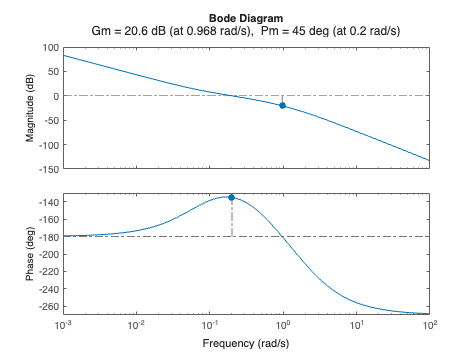

margin(L)

### part b

GM = 20.6

GM = 20.6000

a_1 = db2mag(GM)

a_1 = 10.7152

a_1_inv = 1/a_1

a_1_inv = 0.0933

T = 1+L


T =
 
  26.77 s^4 + 68.54 s^3 + 30 s^2 + 6.03 s + 0.4305
  ------------------------------------------------
           26.77 s^4 + 68.54 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


T_sym = K*L_0+1

$$T\_sym = \frac{K\,\left(\beta \,s_{\mathrm{sym}}\,\tau +1\right)}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}\,\tau +1\right)\,\left(s_{\mathrm{sym}}+2\right)}+1$$

poles = double(solve(subs(T_sym == 0, [K beta tau], [K_req beta_req tau_req]), s_sym))

poles =   -0.1375 + 0.0000i
  -0.1766 - 0.1592i
  -0.1766 + 0.1592i
  -2.0696 + 0.0000i


### part c

T_closed = feedback(L, 1)


T_closed =
 
                  6.03 s + 0.4305
  ------------------------------------------------
  26.77 s^4 + 68.54 s^3 + 30 s^2 + 6.03 s + 0.4305
 
Continuous-time transfer function.
Model Properties


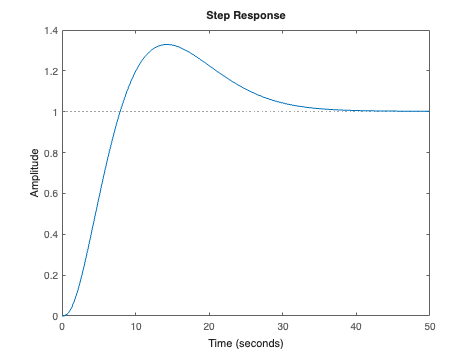

step(T_closed)

stepMetrics = stepinfo(T_closed)

stepMetrics = struct with fields:
         RiseTime: 5.1790
    TransientTime: 33.6079
     SettlingTime: 33.6079
      SettlingMin: 0.9353
      SettlingMax: 1.3289
        Overshoot: 32.8944
       Undershoot: 0
             Peak: 1.3289
         PeakTime: 14.4057


steady_state_value = dcgain(T_closed)

steady_state_value = 1

steady_state_error = 1 - steady_state_value

steady_state_error = 0

### part d

I_new_min = I_nom / a_1

I_new_min = 1.3999

fractional_change = (I_nom - I_new_min) / I_nom

fractional_change = 0.9067

### part e

S = 1/T


S =
 
           26.77 s^4 + 68.54 s^3 + 30 s^2
  ------------------------------------------------
  26.77 s^4 + 68.54 s^3 + 30 s^2 + 6.03 s + 0.4305
 
Continuous-time transfer function.
Model Properties


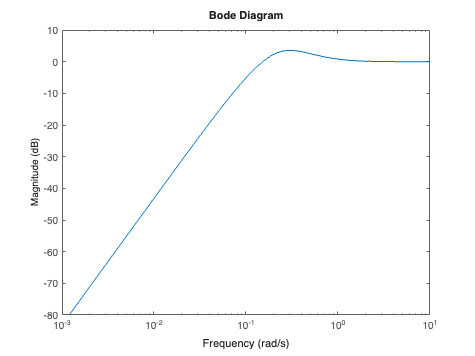

bodemag(S)

## problem 2

### part a

omega_req = 2.5

omega_req = 2.5000

gamma = 45

gamma = 45


ang_L = gamma - 180

ang_L = -135

ang_G = 2*(-90)-2*atand(omega_req/(2+sqrt(omega_req^2+2^2)))

ang_G = -231.3402


beta_phi_eqn = beta == (1+sind(phi_max))/(1-sind(phi_max))

$$beta\_phi\_eqn = \beta =-\frac{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)+1}{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)-1}$$

omega_tau_beta_eqn = omega == 1/(tau*sqrt(beta));

phi_req_old = ang_L - ang_G

phi_req_old = 96.3402

phi_req = (ang_L - ang_G)/2

phi_req = 48.1701


beta_req = double(solve(subs(beta_phi_eqn, phi_max, phi_req), beta))

beta_req = 6.8471

tau_req = double(solve(subs(omega_tau_beta_eqn, [omega beta], [omega_req beta_req]), tau))

tau_req = 0.1529


G_sym = 1/(15*s_sym^2*(s_sym+2))

$$G\_sym = \frac{1}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}+2\right)}$$

H_0 = ((beta*tau*s_sym+1)/(tau*s_sym+1))^2

$$H\_0 = \frac{{\left(\beta \,s_{\mathrm{sym}}\,\tau +1\right)}^{2}}{{\left(s_{\mathrm{sym}}\,\tau +1\right)}^{2}}$$

L_0 = G_sym*H_0

$$L\_0 = \frac{{\left(\beta \,s_{\mathrm{sym}}\,\tau +1\right)}^{2}}{15\,{s_{\mathrm{sym}}}^{2}\,{\left(s_{\mathrm{sym}}\,\tau +1\right)}^{2}\,\left(s_{\mathrm{sym}}+2\right)}$$


K_req = double(solve(subs(abs(L_0)*K == 1, [beta tau s_sym], [beta_req tau_req omega_req*1j]), K))

K_req = 43.8357


G = 1/(15*s^2*(s+2))


G =
 
         1
  ---------------
  15 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


H = K_req*((beta_req*tau_req*s+1)/(tau_req*s+1))^2


H =
 
  48.02 s^2 + 91.76 s + 43.84
  ---------------------------
  0.02337 s^2 + 0.3057 s + 1
 
Continuous-time transfer function.
Model Properties


L = G*H


L =
 
          48.02 s^2 + 91.76 s + 43.84
  -------------------------------------------
  0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


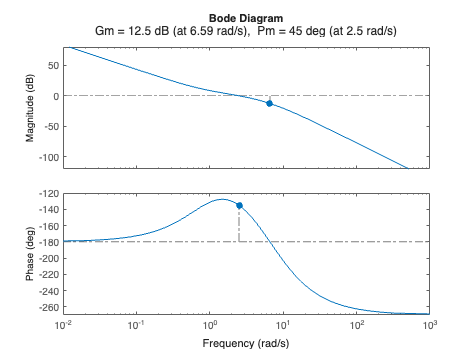

margin(L)

### part b

GM = 12.5

GM = 12.5000

a_1 = db2mag(GM)

a_1 = 4.2170

a_1_inv = 1/a_1

a_1_inv = 0.2371

T = 1+L


T =
 
  0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 78.02 s^2 + 91.76 s + 43.84
  ----------------------------------------------------------------
            0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


T_sym = K*L_0+1

$$T\_sym = \frac{K\,{\left(\beta \,s_{\mathrm{sym}}\,\tau +1\right)}^{2}}{15\,{s_{\mathrm{sym}}}^{2}\,{\left(s_{\mathrm{sym}}\,\tau +1\right)}^{2}\,\left(s_{\mathrm{sym}}+2\right)}+1$$

poles = double(solve(subs(T_sym == 0, [K beta tau], [K_req beta_req tau_req]), s_sym))

poles =   -0.8096 - 0.5186i
  -0.8096 + 0.5186i
  -1.6126 - 3.2576i
  -1.6126 + 3.2576i
 -10.2391 + 0.0000i


### part c

T_closed = feedback(L, 1)


T_closed =
 
                    48.02 s^2 + 91.76 s + 43.84
  ----------------------------------------------------------------
  0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 78.02 s^2 + 91.76 s + 43.84
 
Continuous-time transfer function.
Model Properties


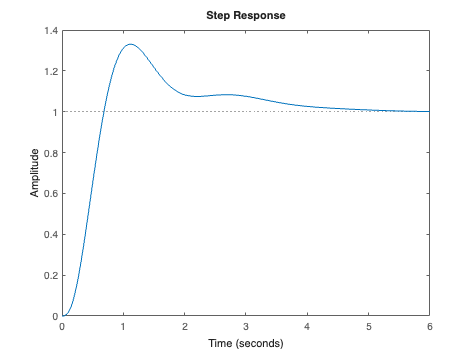

step(T_closed)

stepMetrics = stepinfo(T_closed)

stepMetrics = struct with fields:
         RiseTime: 0.4246
    TransientTime: 4.2505
     SettlingTime: 4.2505
      SettlingMin: 0.9064
      SettlingMax: 1.3301
        Overshoot: 33.0127
       Undershoot: 0
             Peak: 1.3301
         PeakTime: 1.1154


steady_state_value = dcgain(T_closed)

steady_state_value = 1

steady_state_error = 1 - steady_state_value

steady_state_error = 0

### part d

I_new_min = I_nom / a_1

I_new_min = 3.5571

fractional_change = (I_nom - I_new_min) / I_nom

fractional_change = 0.7629

### part e

S = 1/T


S =
 
            0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 30 s^2
  ----------------------------------------------------------------
  0.3505 s^5 + 5.287 s^4 + 24.17 s^3 + 78.02 s^2 + 91.76 s + 43.84
 
Continuous-time transfer function.
Model Properties


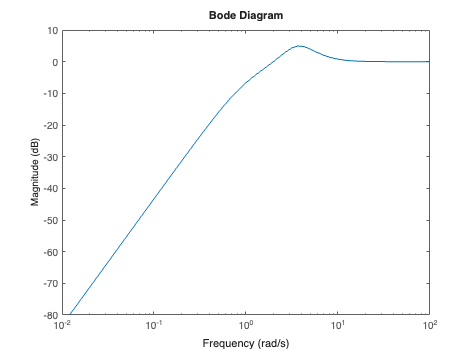

bodemag(S)

## problem 3

### part a

syms z_1 z_2 p_1;

omega_req = 0.2

omega_req = 0.2000

gamma = 45

gamma = 45

I_nom = 15

I_nom = 15


ang_L = gamma - 180

ang_L = -135

ang_G = 3*(-90)-2*atand(omega_req/(2+sqrt(omega_req^2+2^2)))

ang_G = -275.7106


beta_phi_eqn = beta == (1+sind(phi_max))/(1-sind(phi_max))

$$beta\_phi\_eqn = \beta =-\frac{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)+1}{\sin\left(\frac{\pi \,\varphi_{\max}}{180}\right)-1}$$

omega_tau_beta_eqn = omega == 1/(tau*sqrt(beta));

phi_req_old = ang_L - ang_G

phi_req_old = 140.7106

phi_req = (ang_L - ang_G)/2

phi_req = 70.3553


beta_req = double(solve(subs(beta_phi_eqn, phi_max, phi_req), beta))

beta_req = 33.3616

tau_req = double(solve(subs(omega_tau_beta_eqn, [omega beta], [omega_req beta_req]), tau))

tau_req = 0.8657


z_1 = 1/(beta_req*tau_req)

z_1 = 0.0346

z_2 = abs(omega_req/tand(phi_req))

z_2 = 0.0714

p_2 = 1/tau_req

p_2 = 1.1552


G_sym = 1/(15*s_sym*(s_sym+2))

$$G\_sym = \frac{1}{15\,s_{\mathrm{sym}}\,\left(s_{\mathrm{sym}}+2\right)}$$

H_0 = ((s_sym+z_1)*(s_sym+z_2))/(s_sym*(s_sym+p_2))

$$H\_0 = \frac{\left(s_{\mathrm{sym}}+\frac{5144384438151303}{72057594037927936}\right)\,\left(s_{\mathrm{sym}}+\frac{4990183521870499}{144115188075855872}\right)}{s_{\mathrm{sym}}\,\left(s_{\mathrm{sym}}+\frac{5202510925478517}{4503599627370496}\right)}$$

L_0 = G_sym*H_0

$$L\_0 = \frac{\left(s_{\mathrm{sym}}+\frac{5144384438151303}{72057594037927936}\right)\,\left(s_{\mathrm{sym}}+\frac{4990183521870499}{144115188075855872}\right)}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}+\frac{5202510925478517}{4503599627370496}\right)\,\left(s_{\mathrm{sym}}+2\right)}$$


K_req = double(solve(subs(1/abs(L_0) == K, [beta tau s_sym], [beta_req tau_req omega_req*1j]), K))

K_req = 32.8014


G = 1/(15*s^2*(s+2))


G =
 
         1
  ---------------
  15 s^3 + 30 s^2
 
Continuous-time transfer function.
Model Properties


H = K_req*((s+z_1)*(s+z_2))/(s*(s+p_2))


H =
 
  32.8 s^2 + 3.478 s + 0.08109
  ----------------------------
         s^2 + 1.155 s
 
Continuous-time transfer function.
Model Properties


L = G*H


L =
 
   32.8 s^2 + 3.478 s + 0.08109
  ------------------------------
  15 s^5 + 47.33 s^4 + 34.66 s^3
 
Continuous-time transfer function.
Model Properties


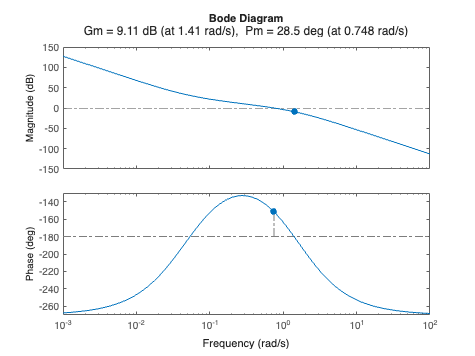

margin(L)

### part b

GM = 9.11

GM = 9.1100

a_1 = db2mag(GM)

a_1 = 2.8543

a_1_inv = 1/a_1

a_1_inv = 0.3503

T = 1+L


T =
 
  15 s^5 + 47.33 s^4 + 34.66 s^3 + 32.8 s^2 + 3.478 s + 0.08109
  -------------------------------------------------------------
                 15 s^5 + 47.33 s^4 + 34.66 s^3
 
Continuous-time transfer function.
Model Properties


T_sym = K*L_0+1

$$T\_sym = \frac{K\,\left(s_{\mathrm{sym}}+\frac{5144384438151303}{72057594037927936}\right)\,\left(s_{\mathrm{sym}}+\frac{4990183521870499}{144115188075855872}\right)}{15\,{s_{\mathrm{sym}}}^{2}\,\left(s_{\mathrm{sym}}+\frac{5202510925478517}{4503599627370496}\right)\,\left(s_{\mathrm{sym}}+2\right)}+1$$

poles = double(solve(subs(T_sym == 0, [K beta tau], [K_req beta_req tau_req]), s_sym))

poles =   -0.0263 - 0.0236i
  -0.0263 + 0.0236i
  -1.5513 - 1.3879i
  -1.5513 + 1.3879i


### part c

T_closed = feedback(L, 1)


T_closed =
 
                  32.8 s^2 + 3.478 s + 0.08109
  -------------------------------------------------------------
  15 s^5 + 47.33 s^4 + 34.66 s^3 + 32.8 s^2 + 3.478 s + 0.08109
 
Continuous-time transfer function.
Model Properties


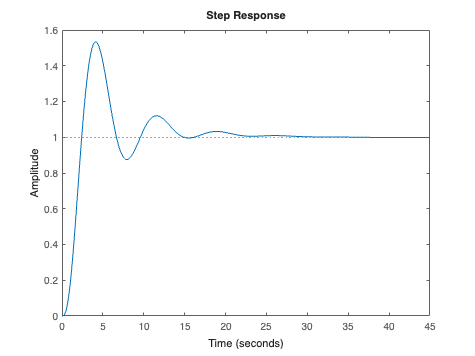

step(T_closed)

stepMetrics = stepinfo(T_closed)

stepMetrics = struct with fields:
         RiseTime: 1.4596
    TransientTime: 20.7047
     SettlingTime: 20.7047
      SettlingMin: 0.8759
      SettlingMax: 1.5328
        Overshoot: 53.2804
       Undershoot: 0
             Peak: 1.5328
         PeakTime: 4.1146


steady_state_value = dcgain(T_closed)

steady_state_value = 1

steady_state_error = 1 - steady_state_value

steady_state_error = 0

### part d

I_new_min = I_nom / a_1

I_new_min = 5.2552

fractional_change = (I_nom - I_new_min) / I_nom

fractional_change = 0.6497

### part e

S = 1/T


S =
 
                 15 s^5 + 47.33 s^4 + 34.66 s^3
  -------------------------------------------------------------
  15 s^5 + 47.33 s^4 + 34.66 s^3 + 32.8 s^2 + 3.478 s + 0.08109
 
Continuous-time transfer function.
Model Properties


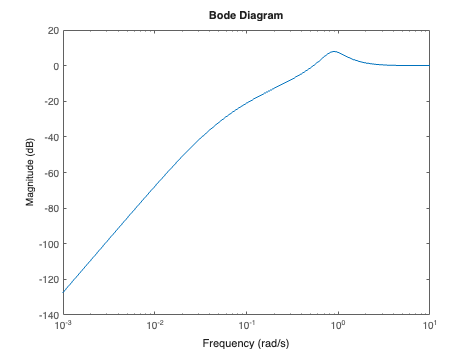

bodemag(S)